T = [30.1 35 40 45 50 55 60];
sigma = [63.08 63.17 62.48 62.06 61.63 61.03 60.60];
mean(T)

ans = 45.0143

mean(sigma)

ans = 62.0071

mean(T.^2)

ans = 2.1259e+03

mean(sigma.^2)

ans = 3.8457e+03

mean(T.*sigma)

ans = 2.7822e+03


fg1 = figure

fg1 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


grid on
hold on

xlim([0,60]);
plot(T, sigma, '+r');
xi = min(0):0.1:max(T);
N = 1; % степень
coeff1 = polyfit(T, sigma, N)

coeff1 =    -0.0900   66.0592


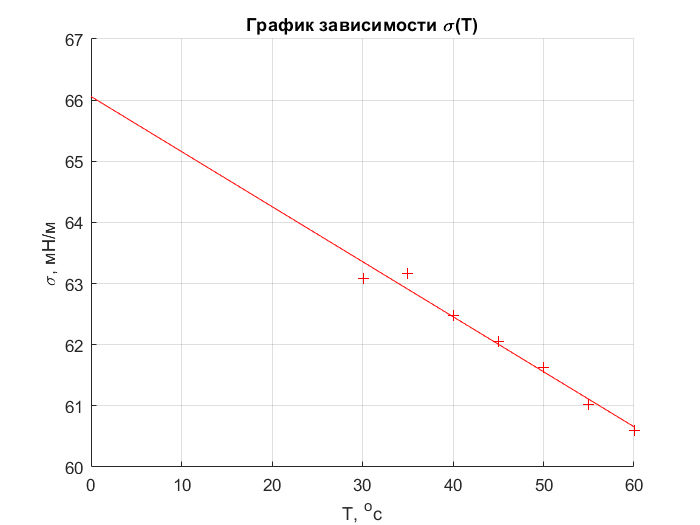

y2 = 0;
for k=0:N
    y2 = y2 + coeff1(N-k+1) * xi.^k;
end
gr1 = plot(xi, y2, 'r'); 
xlabel(['T, ^oc'])
ylabel("\sigma, мН/м")
title("График зависимости \sigma(T)")

set(fg1, "Visible", 'on')

 
hold off 